# Esercizi per l'esame

## Aritmetica Finita - 6

Come richieso implementiamo il calcolo del seno iperbolico tramite definizione

simple_sinh = @(x) (exp(x)-exp(-x))./2;

Adesso calcoliamo l'errore assoluto, prendendo come valore di riferimento l'implementazione interna di MATLAB del seno iperbolico. Valuteremo gli errori per $x={10}^{-12} ,{10}^{-11} ,\ldotp \ldotp \ldotp ,{10}^{-1} ,{10}^0$

asse_x = 10.^(-12:0);
errore_assoluto = abs(sinh(asse_x)-simple_sinh(asse_x));

Calcoliamo quindi l'errore relativo con le stesse procedure

errore_relativo = errore_assoluto./sinh(asse_x);

Disegnamo infine un unico grafico (con due assi verticali) dove rappresentare gli errori relativi e assoluti.

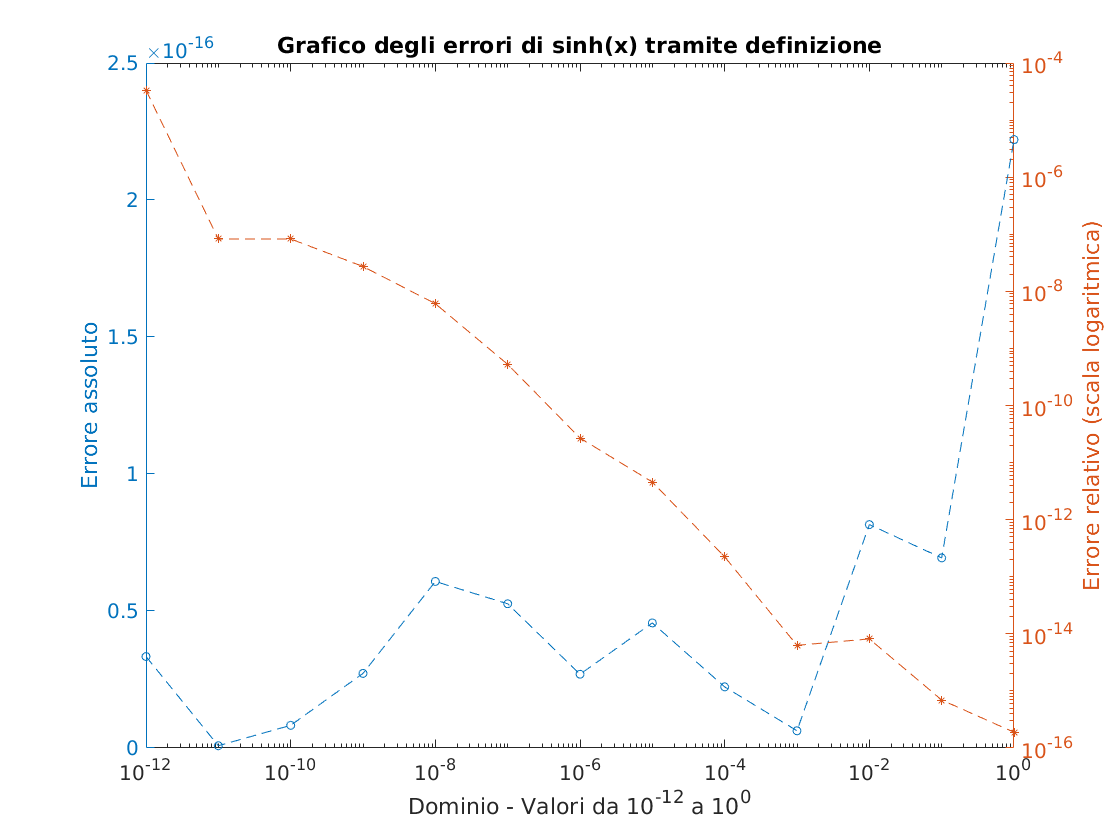

figure();
title('Grafico degli errori di sinh(x) tramite definizione');
xlabel('Dominio - Valori da 10^{-12} a 10^0');
yyaxis left;
semilogx(asse_x,errore_assoluto,'--o');
ylabel('Errore assoluto');
yyaxis right;
loglog(asse_x,errore_relativo,'--*');
ylabel('Errore relativo (scala logaritmica)');

Come si può notare, l'errore relativo aumenta per piccoli valori di x. Questo è giustificato poichè il numeratore della definizione del seno iperbolico presenta una differenza di quantità tra quantità che diventano tanto più prossime quanto più $x$ è piccolo, portando quindi ad un fenomeno di cancellazione numerica.

## Aritmetica Finita - 7

Continuando con i dati dell'esericzio precedente, implementiamo il calcolo del seno iperbolico in modo da evitare fenomeni di cancellazione numerica.

mio_sinh = @(x) (expm1(x)+expm1(x)./(expm1(x)+1))/2;

Ora calcoliamo e disegnamo il grafico dell'errore relativo i quest'ultima implementazione contro quella interna a MATLAB

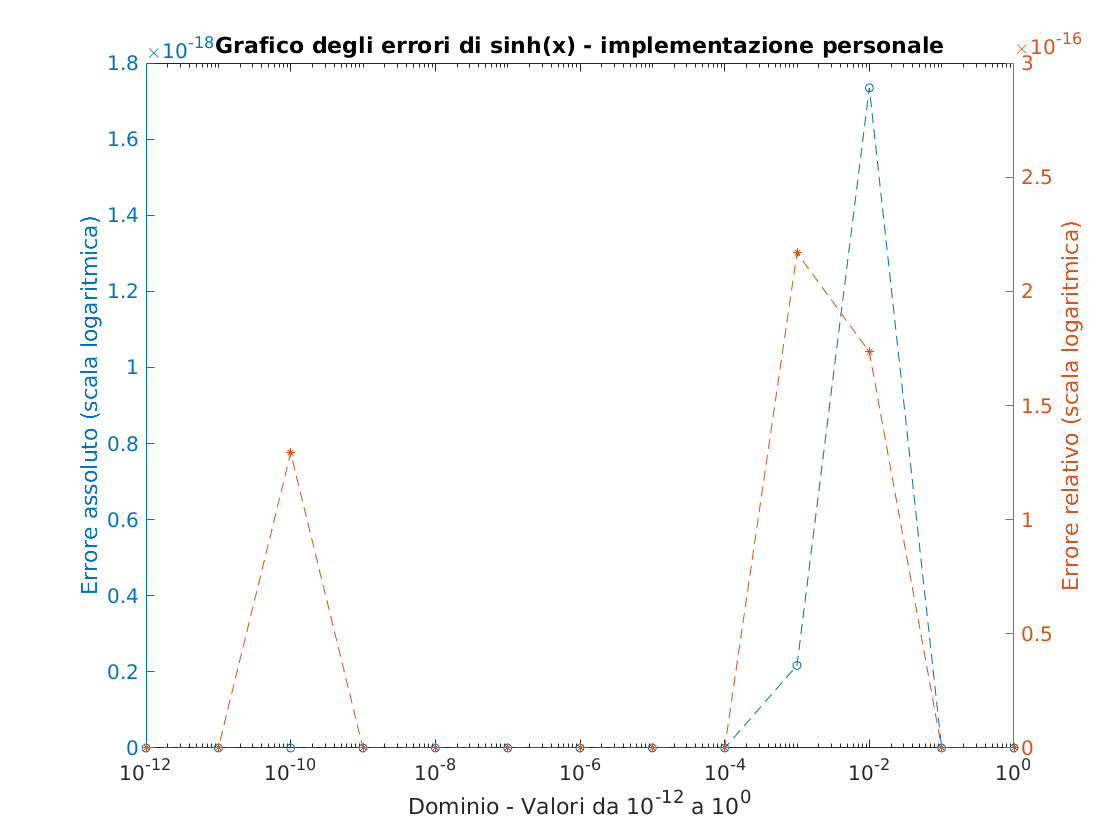

figure();
mio_errore_assoluto = abs(sinh(asse_x)-mio_sinh(asse_x));
mio_errore_relativo = mio_errore_assoluto./sinh(asse_x);
title('Grafico degli errori di sinh(x) - implementazione personale');
xlabel('Dominio - Valori da 10^{-12} a 10^0');
yyaxis left;
semilogx(asse_x,mio_errore_assoluto,'--o');
ylabel('Errore assoluto (scala logaritmica)');
yyaxis right;
semilogx(asse_x,mio_errore_relativo,'--*');
ylabel('Errore relativo (scala logaritmica)');

## Aritmetica Finita - 8

Definiamo, come richiesto, una espressione matematicamente equivalente alla differenza divisa di ordine uno di $f\left(x\right)=x^3$ ma priva di cancellazione numerica:


$$f\left\lbrack x_0 ,x_0 +h\right\rbrack =\frac{f\left(x_0 +h\right)-f\left(x_0 \right)}{h}=\frac{{\left(x_0 +h\right)}^3 -x_0^3 }{h}=\frac{x_0^3 +3x_0^2 h+3x_0 h^2 +h^3 -x_0^3 }{h}=3x_0^2 +3x_0 h+h^2$$


Si può notare come l'ultima espressione sia esente da cancellazione numerica in quanto è solo la somma di quantità strettamente positive.

Calcoliamo ora i valori delle due differenze divise per specifici valori di $x$ e di $h$

asse_x = 10.^(1:4);
h = 10^-7;
differenza_divisa = ((asse_x+h).^3-(asse_x).^3)/h;
differenza_divisa_no_err = 3*(asse_x).^2 + 3*asse_x*h + h^2;

Calcoliamo gli errori richiesti

errore_assoluto = abs(differenza_divisa - 3*asse_x.^2);
errore_assoluto_no_err = abs(differenza_divisa_no_err - 3*asse_x.^2);
errore_relativo = errore_assoluto./abs(3*asse_x.^2);
errore_relativo_no_err = errore_assoluto_no_err./abs(3*asse_x.^2);

Infine disegnamo i grafici dei vari errori

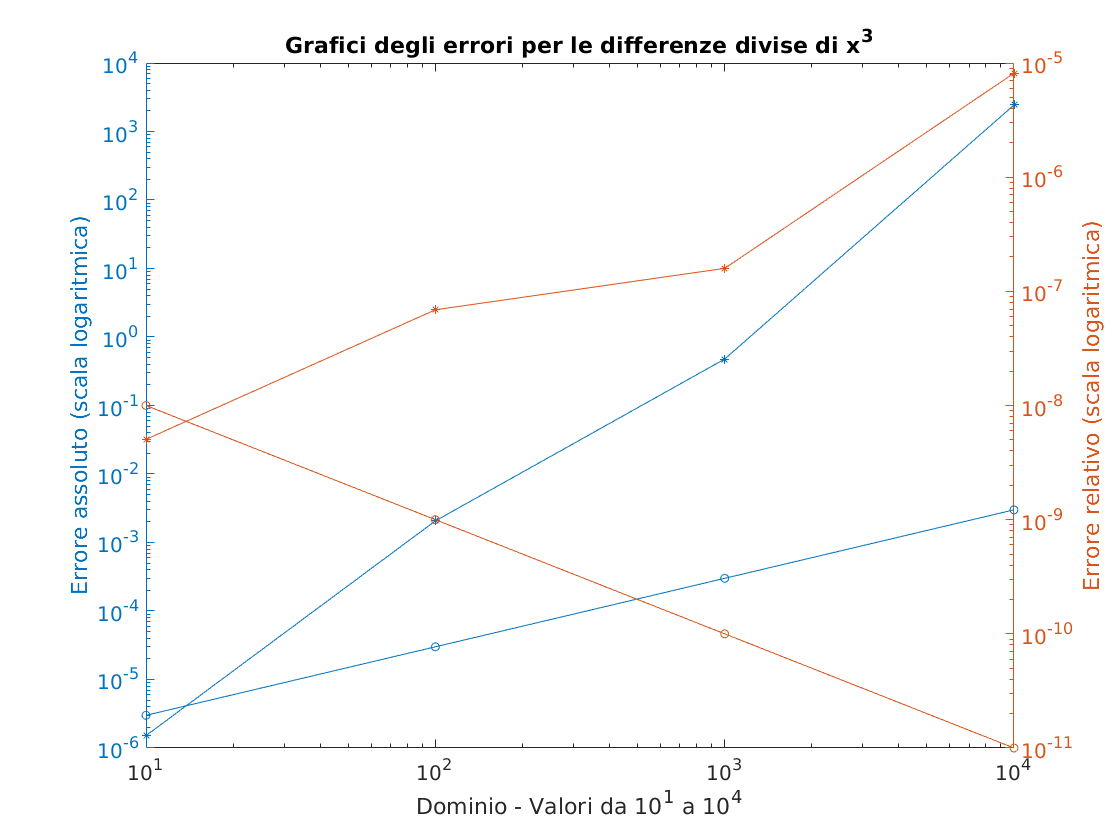

figure();
title('Grafici degli errori per le differenze divise di x^3');
xlabel('Dominio - Valori da 10^1 a 10^4');
yyaxis left;
loglog(asse_x,errore_assoluto,'*-',asse_x,errore_assoluto_no_err,'o-');
ylabel('Errore assoluto (scala logaritmica)');
yyaxis right;
loglog(asse_x,errore_relativo,'*-',asse_x,errore_relativo_no_err,'o-');
ylabel('Errore relativo (scala logaritmica)');

Ripetendo lo stesso esercizio con $f\left(x\right)=x^5$ otteniamo


$$f\left\lbrack x_0 ,x_0 +h\right\rbrack =\frac{f\left(x_0 +h\right)-f\left(x_0 \right)}{h}=\frac{{\left(x_0 +h\right)}^5 -x_0^5 }{h}=\dots =5x_0^4 +10x_0^3 h+10x_0^2 h^2 +5x_0 h^3 +h^4$$


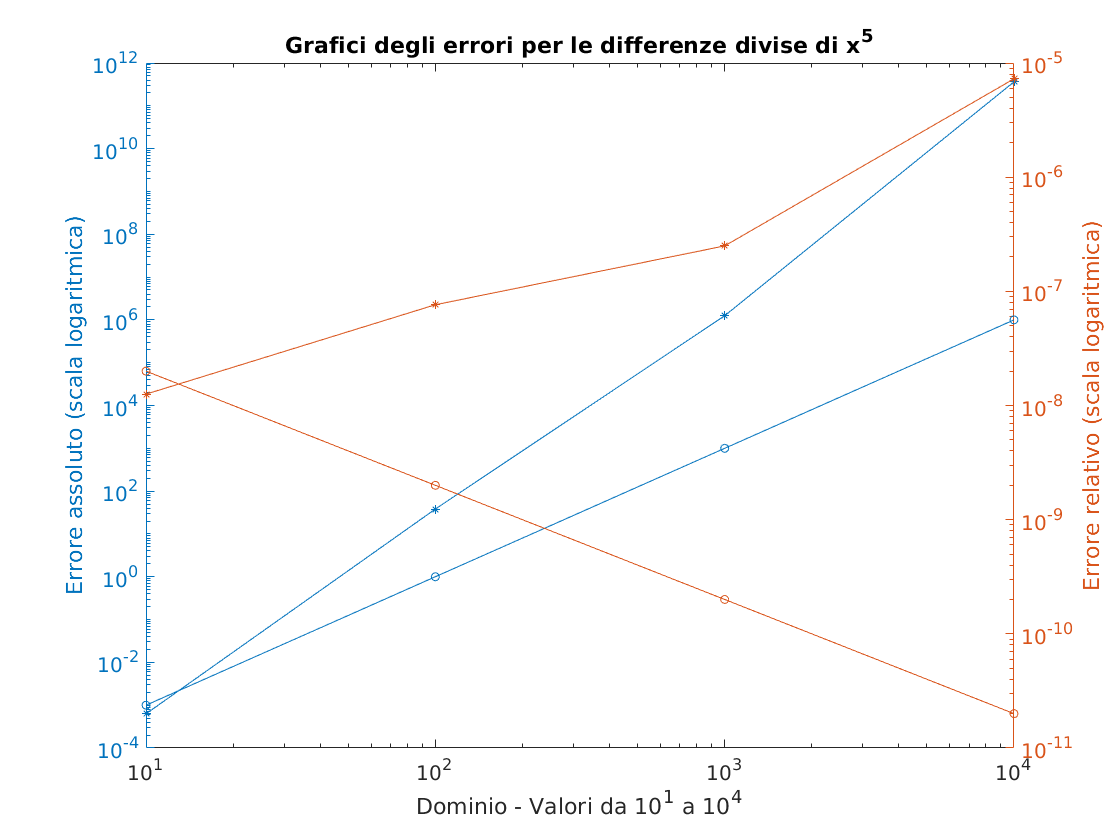

differenza_divisa = ((asse_x+h).^5-(asse_x).^5)/h;
differenza_divisa_no_err = 5*(asse_x).^4 + 10*asse_x.^3*h + 10*asse_x.^2*h^2 + h^4;
errore_assoluto = abs(differenza_divisa - 5*asse_x.^4);
errore_assoluto_no_err = abs(differenza_divisa_no_err - 5*asse_x.^4);
errore_relativo = errore_assoluto./abs(5*asse_x.^4);
errore_relativo_no_err = errore_assoluto_no_err./abs(5*asse_x.^4);
figure();
title('Grafici degli errori per le differenze divise di x^5');
xlabel('Dominio - Valori da 10^1 a 10^4');
yyaxis left;
loglog(asse_x,errore_assoluto,'*-',asse_x,errore_assoluto_no_err,'o-');
ylabel('Errore assoluto (scala logaritmica)');
yyaxis right;
loglog(asse_x,errore_relativo,'*-',asse_x,errore_relativo_no_err,'o-');
ylabel('Errore relativo (scala logaritmica)');

## Vettori, matrici e sistemi lineari - 8

Viene data una matrice definita così:

$A=\left\lbrack \begin{array}{cc}
A_{11}  & A_{12} \\
0 & A_{22} 
\end{array}\right\rbrack$    dove $A_{11} \in \Re^{p\times p} ,A_{12} \in \Re^{p\times q} ,A_{22} \in \Re^{q\times q}$

Viene chiesto di calcolare in funzione di $q$ il numero di moltiplicazioni totali necessarie per la risoluzione del sistema lineare (eliminazione gaussiana più sostituzione all’indietro).

Considerando la matrice $A$ come una semplice matrice di ordine $n=p+q$, è ben noto che sono necessarie circa $\frac{1}{3}n^3 +\frac{1}{2}n^2$ moltiplicazioni per la completa risoluizione di un sistema lineare. Ovvero, in funzione di $q$ si ha $\frac{1}{3}{\left(q+p\right)}^3 +\frac{1}{2}{\left(p+q\right)}^2$.

Invece, utilizzando la decomposizione a blocchi ed immaginando anche $\overrightarrow{x}$ e $\overrightarrow{b}$ a blocchi, si nota che:


$$\left\lbrack \begin{array}{cc}
A_{11}  & A_{12} \\
0 & A_{22} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
b_1 \\
b_2 
\end{array}\right\rbrack \Rightarrow \left\lbrack \begin{array}{c}
A_{11} \;x_1 +A_{12} \;x_2 \\
A_{22} \;x_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
b_1 \\
b_2 
\end{array}\right\rbrack$$


Dalla equazione inferiore notiamo che può essere calcolato $x_2$ tramite un sistema lineare di ordine $q$, ovvero con $\frac{1}{3}q^3 +\frac{1}{2}q^2$ moltiplicazioni. Poi, sostituendo nell'equazione superiore, si ricava $A_{11} \;x_1 =b_1 -A_{12} \;x_2$. Tale operazione richiede il prodotto matrice vettore, ovvero $p*q$ moltiplicazioni. Anche queso sistema è lineare e si risolve con $\frac{1}{3}p^3 +\frac{1}{2}p^2$ moltiplicazioni. Ovvero utilizzando la forma a blocchi della matrice $A$, si risolve il sistema lineare in $\frac{1}{3}q^3 +\frac{1}{2}q^2 +\frac{1}{3}p^3 +\frac{1}{2}p^2 +p*q$ moltiplicazioni.

tempo_teorico_modo1 = @(q,n) ones(size(q)).*(n.^3/3 + n.^2/2);
tempo_teorico_modo2 = @(q,n) q.^3/3 + q.^2/2 + (n-q).^3/3 + (n-q).^2/2 + (n-q).*q;

## Vettori, matrici e sistemi lineari - 9

Come richiesto, effettiamo la misurazione dei tempi di esecuzione dei due metodi di risoluzione.

n = 5000;
s = 250;
asse_x = s:s:(n-s);
tempi_modo1 = zeros(n/s-1,1);
tempi_modo2 = zeros(n/s-1,1);
for q = asse_x
    p = n - q;
    A11 = rand(p,p);
    A12 = rand(p,q);
    A22 = rand(q,q);
    b1 = ones(p,1);
    b2 = ones(q,1);
    A = [A11,A12;zeros(q,p),A22];
    b = [b1;b2];
    
    tic;
    x = A\b;
    tempi_modo1(q/s) = toc();
    
    tic;
    x2 = A22\b2;
    x1 = A11\(b1-A12*x2);
    tempi_modo2(q/s) = toc();
end

Riportiamo quindi il grafico dei tempi ottenuti

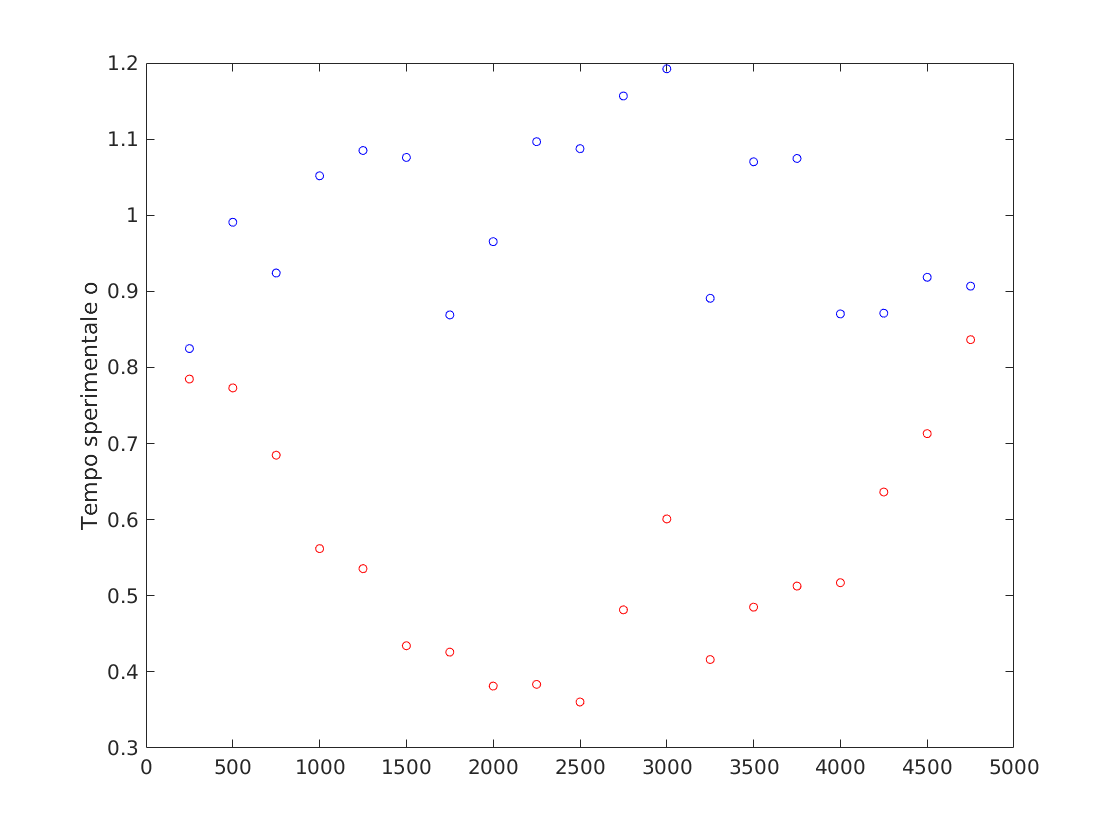

figure();
plot(asse_x,tempi_modo1,'ob',asse_x,tempi_modo2,'or');
ylabel('Tempo sperimentale o');

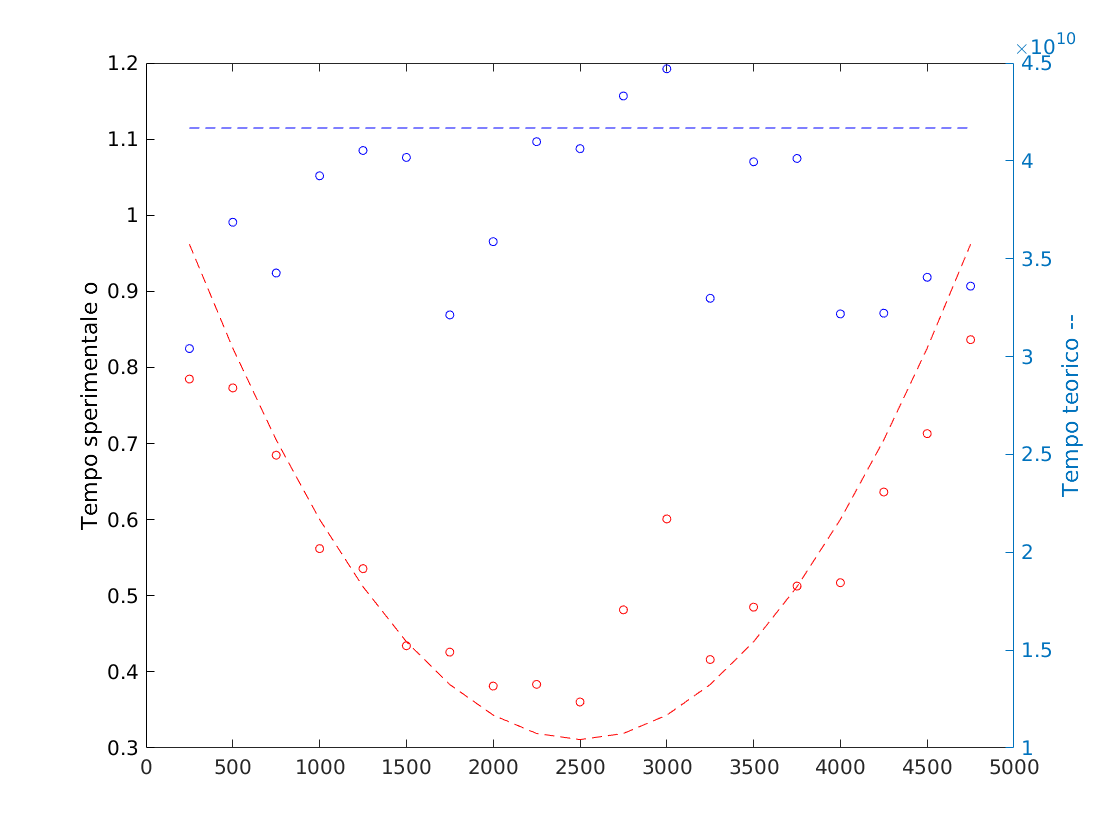

yyaxis right;
plot(asse_x,tempo_teorico_modo1(asse_x,n),'--b',asse_x,tempo_teorico_modo2(asse_x,n),'--r');
ylabel('Tempo teorico --');